resolution = 1200;
fs = 8000;
duration = 0.1;
gap = 0.1;

filter_order = 5;
passband_ripple = 0.2;
stopband_attenuation = 50;

delta = [1 zeros(1, 500)];

## Lo-f1

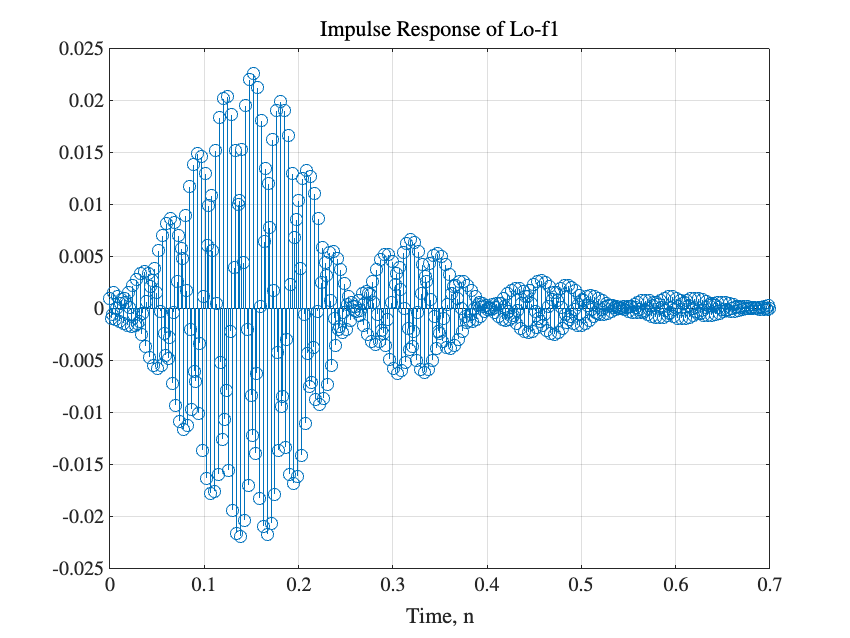

[~, b,a] = cheby2_HL_filter([],fs/4, filter_order, 677, 717, passband_ripple, stopband_attenuation);

h = filter(b,a,delta);
stem(linspace(0,0.7,length(delta)),h)
title('Impulse Response of Lo-f1')
xlabel('Time, n')
grid on

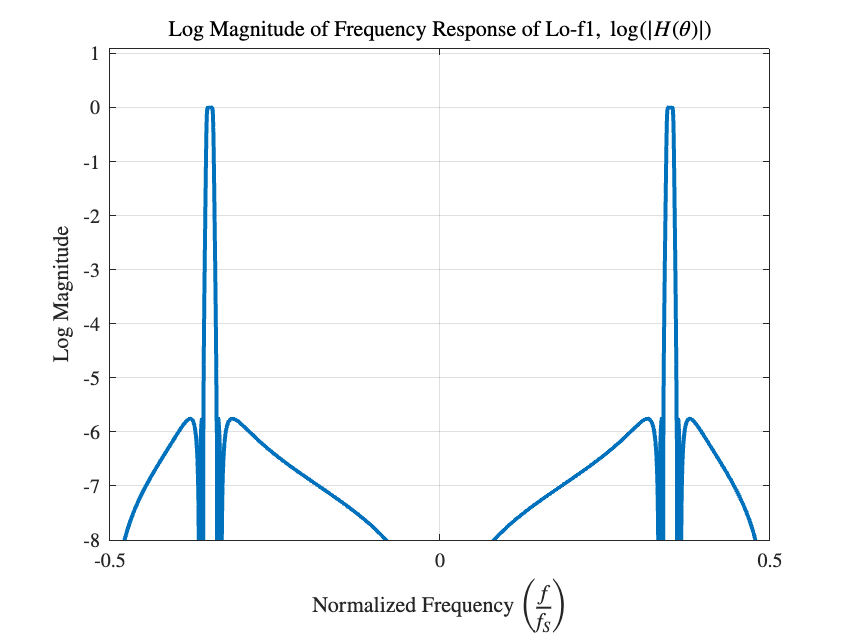


% exportgraphics(gcf, 'TeX/images/4E_LoF1_Impulse.png', 'Resolution',resolution);

figure()
[H,~]=freqz(b,a,fs/4,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response of Lo-f1, $\log(|H(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/4E_LoF1_Frequency.png', 'Resolution',resolution);

## Lo-f2

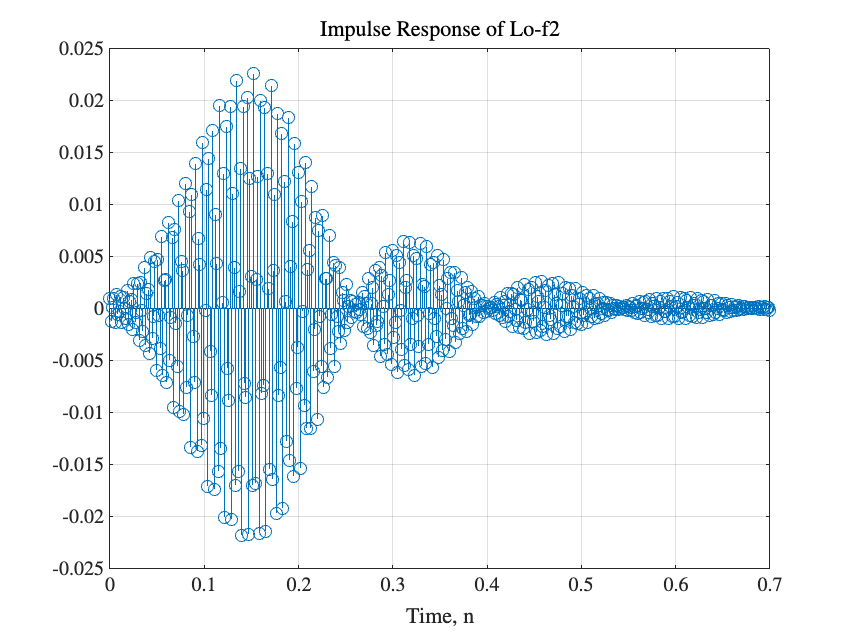

[~, b,a] = cheby2_HL_filter([],fs/4, filter_order, 750, 790, passband_ripple, stopband_attenuation);

h = filter(b,a,delta);
stem(linspace(0,0.7,length(delta)),h)
title('Impulse Response of Lo-f2')
xlabel('Time, n')
grid on

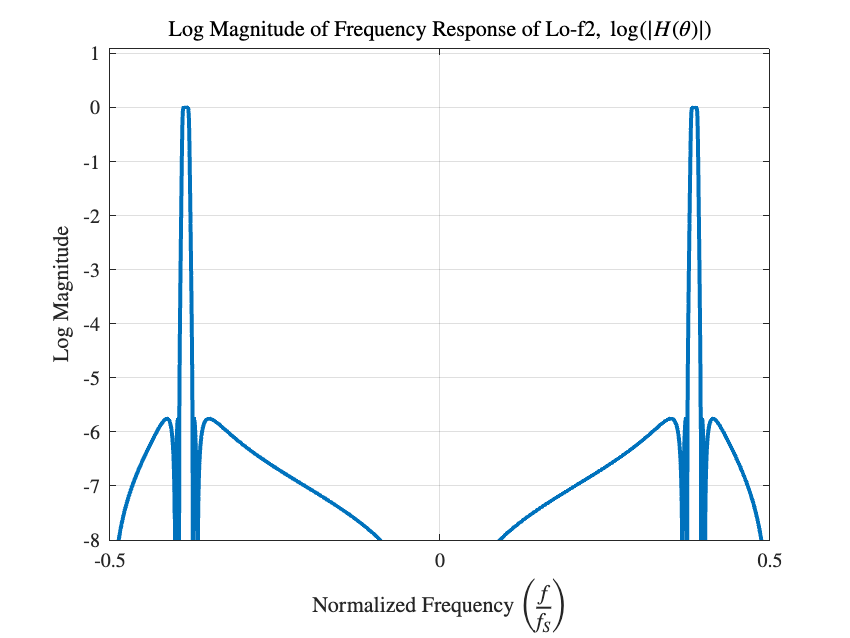

% exportgraphics(gcf, 'TeX/images/4E_LoF2_Impulse.png', 'Resolution',resolution);

figure()
[H,~]=freqz(b,a,fs/4,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response of Lo-f2, $\log(|H(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/4E_LoF2_Frequency.png', 'Resolution',resolution);

## Lo-f3

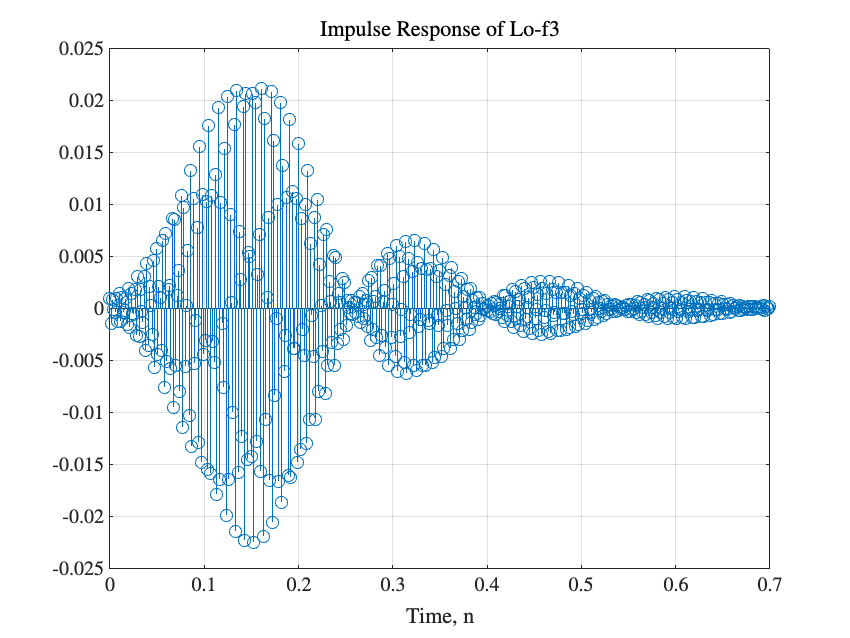

[~, b,a] = cheby2_HL_filter([],fs/4, filter_order, 832, 872, passband_ripple, stopband_attenuation);

h = filter(b,a,delta);
stem(linspace(0,0.7,length(delta)),h)
title('Impulse Response of Lo-f3')
xlabel('Time, n')
grid on

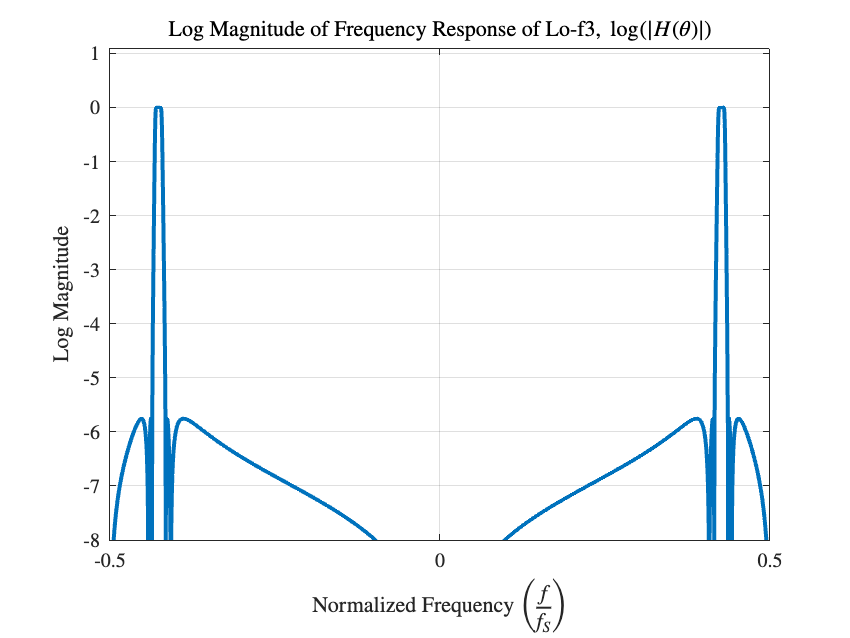


% exportgraphics(gcf, 'TeX/images/4E_LoF3_Impulse.png', 'Resolution',resolution);
figure()
[H,~]=freqz(b,a,fs/4,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response of Lo-f3, $\log(|H(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/4E_LoF3_Frequency.png', 'Resolution',resolution);

## Lo-f4

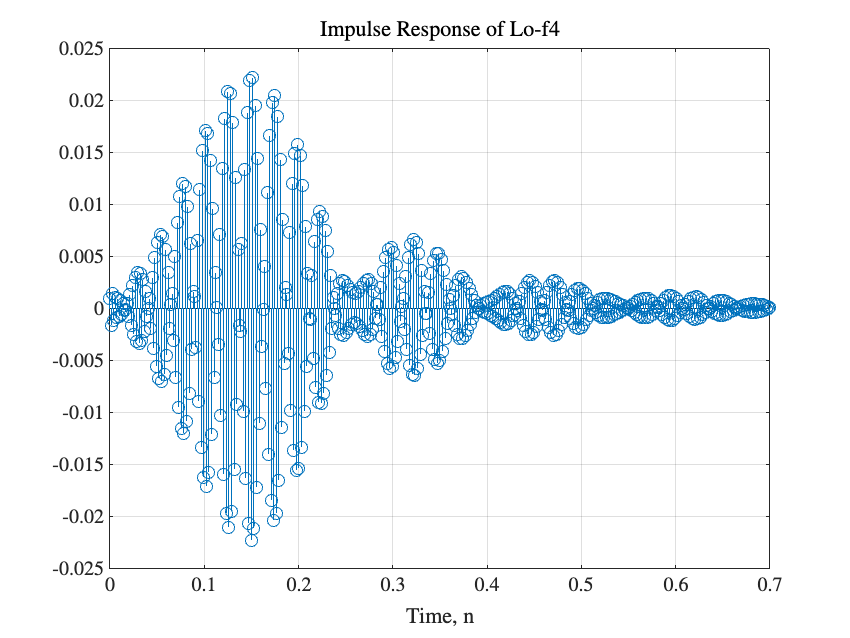

[~, b,a] = cheby2_HL_filter([],fs/4, filter_order, 921, 961, passband_ripple, stopband_attenuation);

h = filter(b,a,delta);
stem(linspace(0,0.7,length(delta)),h)
title('Impulse Response of Lo-f4')
xlabel('Time, n')
grid on

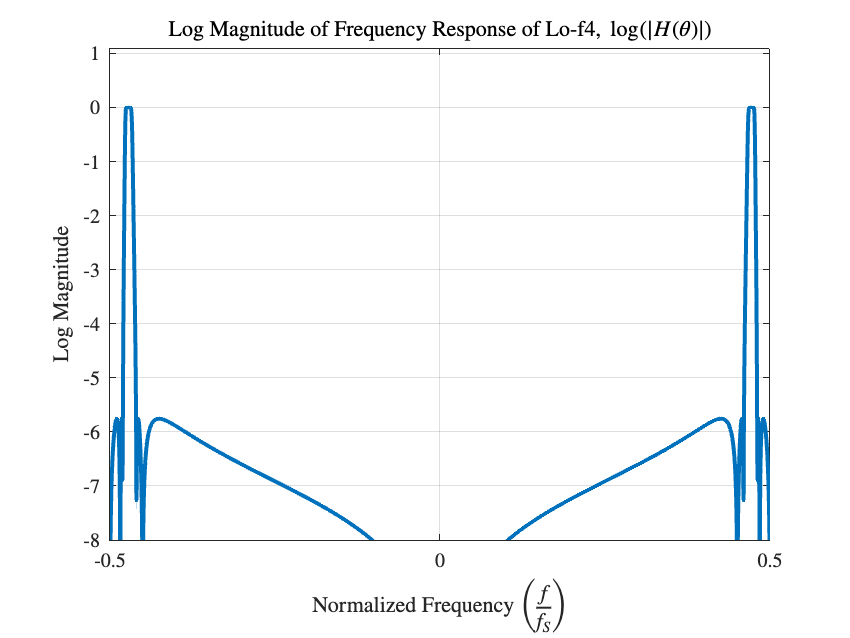


% exportgraphics(gcf, 'TeX/images/4E_LoF4_Impulse.png', 'Resolution',resolution);
figure()
[H,~]=freqz(b,a,fs/4,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response of Lo-f4, $\log(|H(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/4E_LoF4_Frequency.png', 'Resolution',resolution);

## Hi-f1

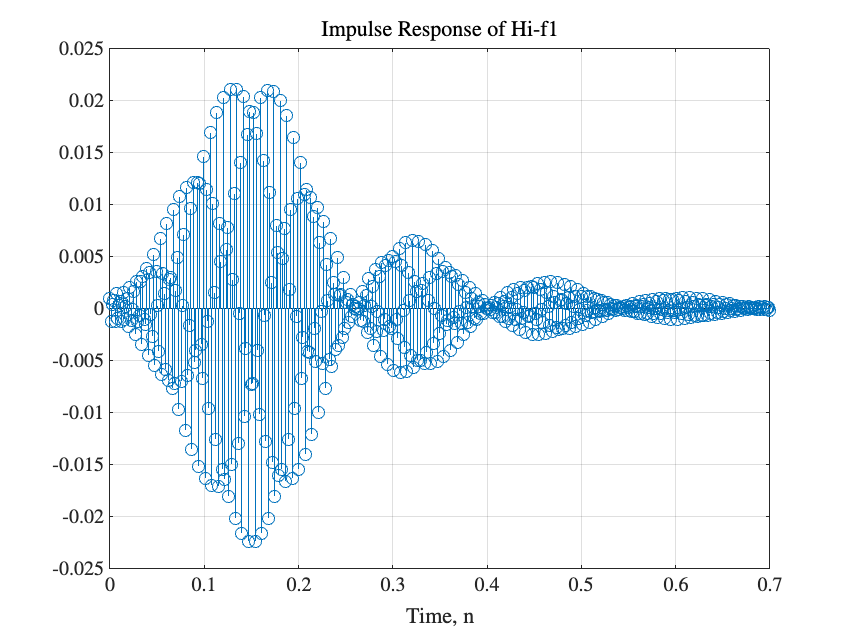

[~, b,a] = cheby2_HL_filter([],fs/4, filter_order, 770, 810, passband_ripple, stopband_attenuation);

h = filter(b,a,delta);
stem(linspace(0,0.7,length(delta)),h)
title('Impulse Response of Hi-f1')
xlabel('Time, n')
grid on

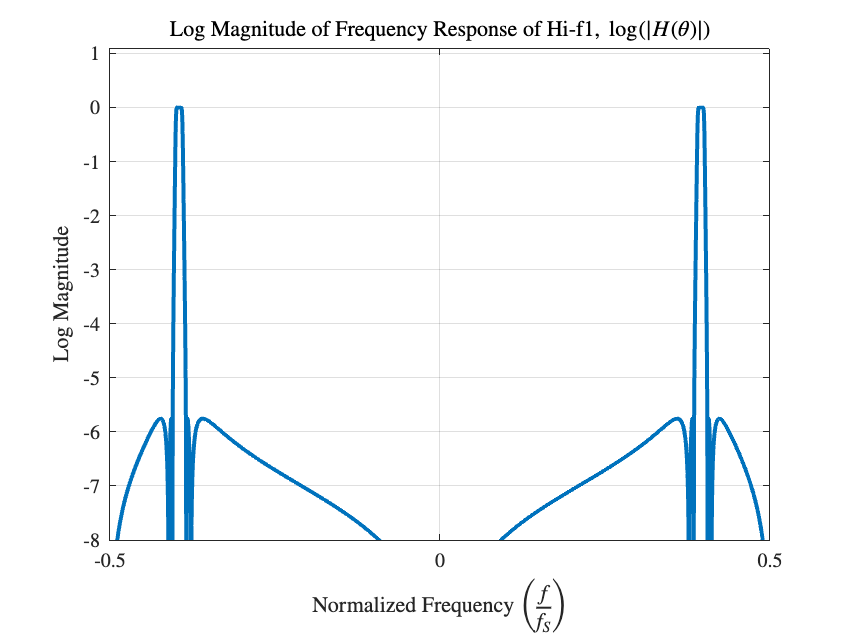

% exportgraphics(gcf, 'TeX/images/4E_HiF1_Impulse.png', 'Resolution',resolution);

figure()
[H,~]=freqz(b,a,fs/4,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response of Hi-f1, $\log(|H(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/4E_HiF1_Frequency.png', 'Resolution',resolution);

## Hi-f2

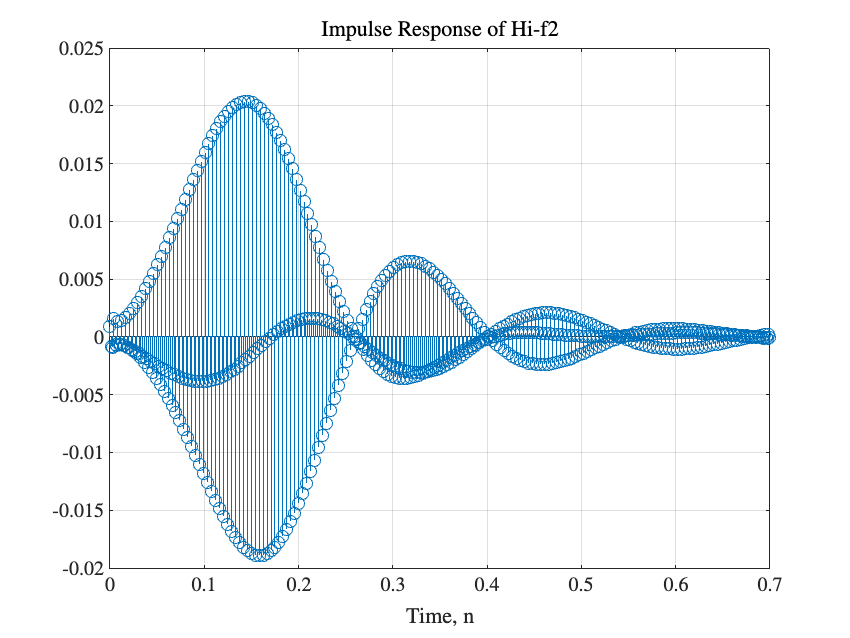

[~, b,a] = cheby2_HL_filter([],fs/4, filter_order, 645, 685, passband_ripple, stopband_attenuation);

h = filter(b,a,delta);
stem(linspace(0,0.7,length(delta)),h)
title('Impulse Response of Hi-f2')
xlabel('Time, n')
grid on

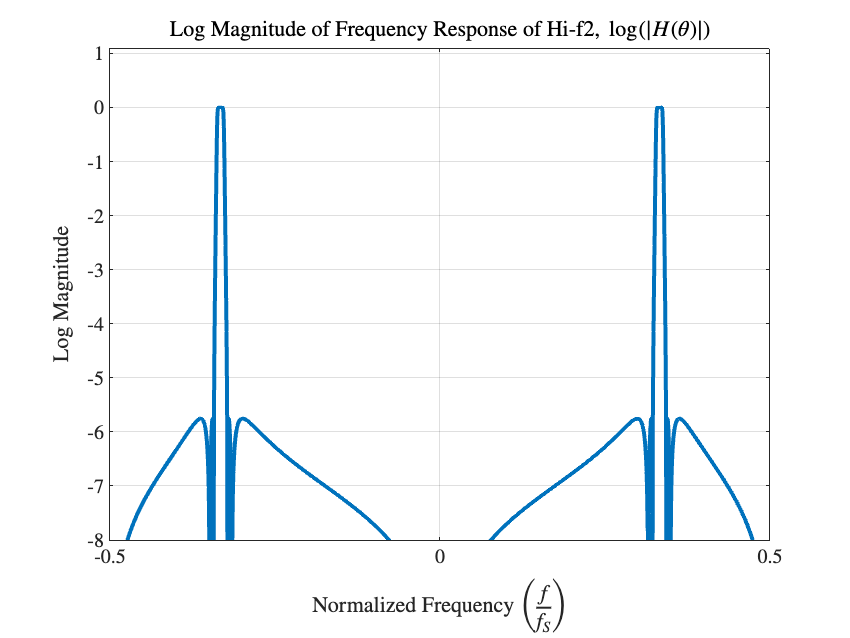


% exportgraphics(gcf, 'TeX/images/4E_HiF2_Impulse.png', 'Resolution',resolution);

figure()
[H,~]=freqz(b,a,fs/4,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response of Hi-f2, $\log(|H(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/4E_HiF2_Frequency.png', 'Resolution',resolution);

## Hi-f3

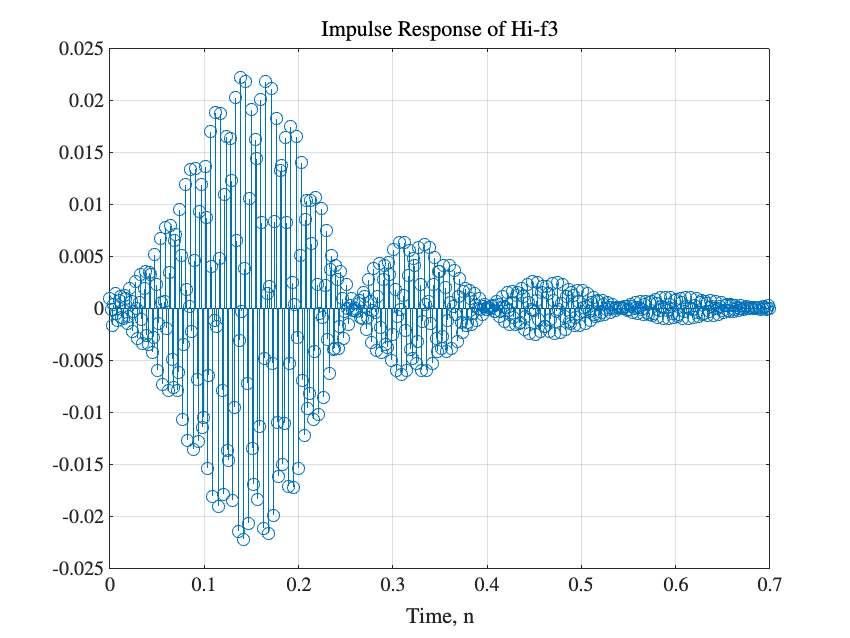

[~, b,a] = cheby2_HL_filter([],fs/4, filter_order, 505, 545, passband_ripple, stopband_attenuation);

h = filter(b,a,delta);
stem(linspace(0,0.7,length(delta)),h)
title('Impulse Response of Hi-f3')
xlabel('Time, n')
grid on

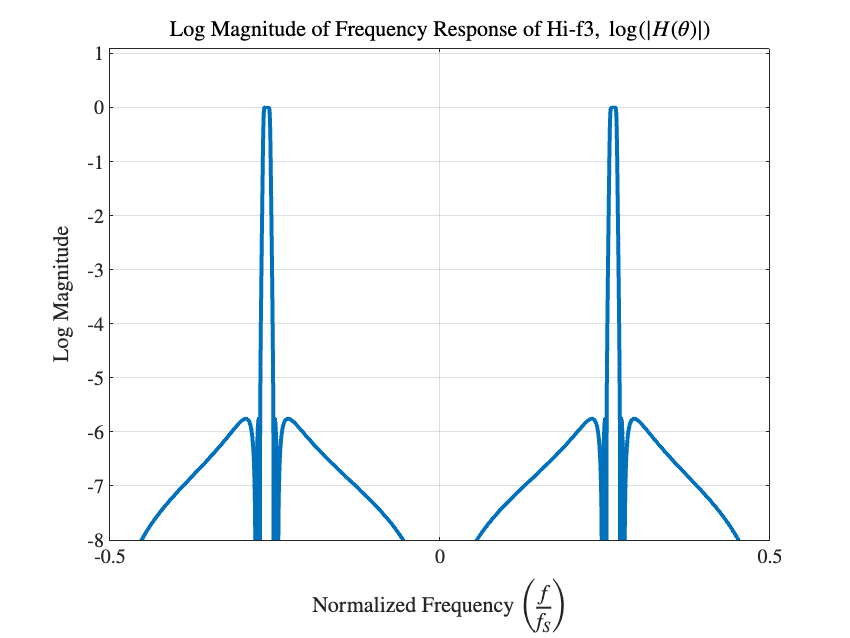


% exportgraphics(gcf, 'TeX/images/4E_HiF3_Impulse.png', 'Resolution',resolution);

figure()
[H,~]=freqz(b,a,fs/4,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response of Hi-f3, $\log(|H(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/4E_HiF3_Frequency.png', 'Resolution',resolution);

## Hi-f4

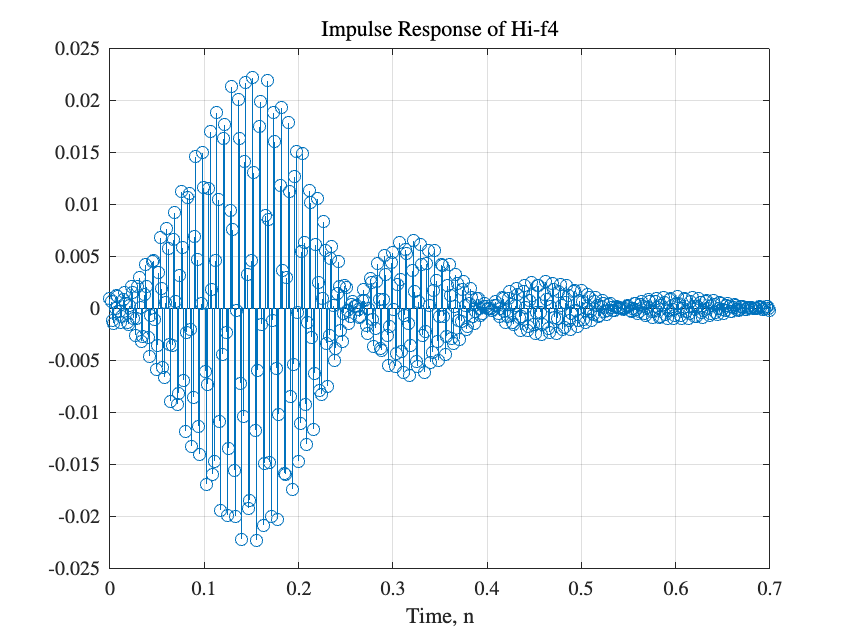

[~, b,a] = cheby2_HL_filter([],fs/4, filter_order, 350, 390, passband_ripple, stopband_attenuation);

h = filter(b,a,delta);
stem(linspace(0,0.7,length(delta)),h)
title('Impulse Response of Hi-f4')
xlabel('Time, n')
grid on

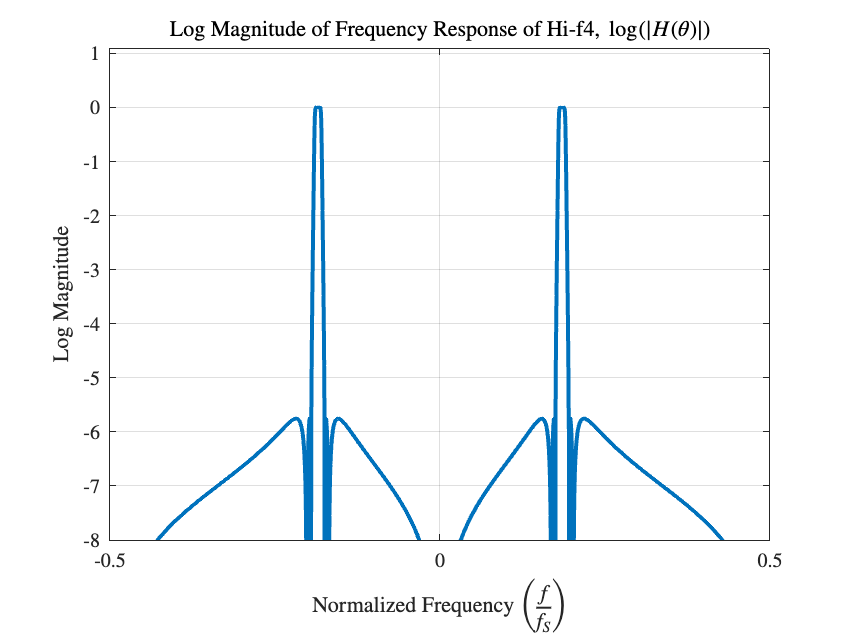


% exportgraphics(gcf, 'TeX/images/4E_HiF4_Impulse.png', 'Resolution',resolution);

figure()
[H,~]=freqz(b,a,fs/4,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response of Hi-f4, $\log(|H(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')

% exportgraphics(gcf, 'TeX/images/4E_HiF4_Frequency.png', 'Resolution',resolution);